# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 07-Jun-2024 06:35:24

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = featureInputLayer(1,"Name","featureinput");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    fullyConnectedLayer(10,"Name","fc")
    reluLayer("Name","relu_1")
    fullyConnectedLayer(10,"Name","fc_1")
    reluLayer("Name","relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","addition");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    fullyConnectedLayer(10,"Name","fc_2")
    reluLayer("Name","relu_3")
    fullyConnectedLayer(10,"Name","fc_3")
    reluLayer("Name","relu_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_1")
    fullyConnectedLayer(10,"Name","fc_4")
    reluLayer("Name","relu_4")
    fullyConnectedLayer(10,"Name","fc_5")
    regressionLayer("Name","regressionoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"featureinput","fc");
lgraph = connectLayers(lgraph,"featureinput","addition/in1");
lgraph = connectLayers(lgraph,"relu","addition/in2");
lgraph = connectLayers(lgraph,"addition","fc_2");
lgraph = connectLayers(lgraph,"addition","addition_1/in2");
lgraph = connectLayers(lgraph,"relu_2","addition_1/in1");

## Plot Layers

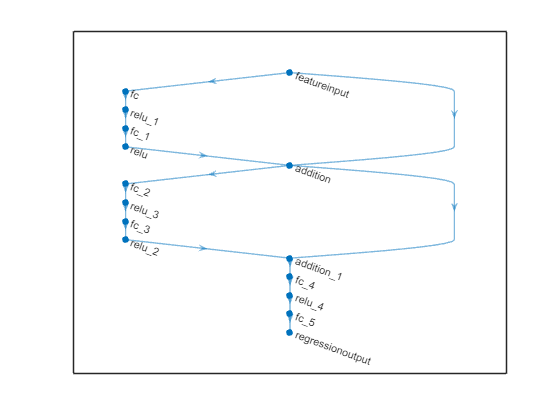

plot(lgraph);